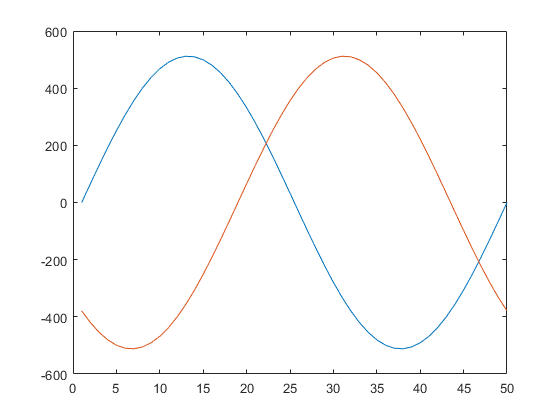

n = 0:49;
a = 512*sin((2*pi/49)*n);
plot(a);

phase = 32;
b = [a(phase:end-1),a(1:phase)];
hold on; plot(b)

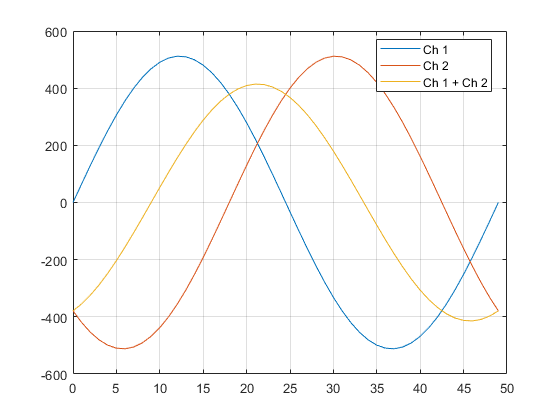


t = n;

C1 = a;
C2 = b;

C1s = [mean(C1); 2*std(C1)];
C2s = [mean(C2); 2*std(C2)];

sinsum = C1 + C2;
sinsums = [mean(sinsum); 2*std(sinsum)];

c_fcn = @(theta) sqrt(C1s(2).^2 + C2s(2).^2 + 2*C1s(2).*C2s(2).*cos(theta)) - sinsums(2);
theta = fzero(c_fcn, 1);
thetadeg = theta*180/pi;

phi_fcn = @(theta) atan2(C2s(2).*sin(theta), C1s(2) + C2s(2).*cos(theta));
phi = fminsearch(@(b)norm(phi_fcn(b)), 1);

figure
plot(t, C1,   t, C2,    t, sinsum)
grid
legend('Ch 1', 'Ch 2', 'Ch 1 + Ch 2', 'Location','best')
text(250, 2, sprintf('\\theta = %.3f rad = %.3f\\circ', theta, thetadeg))